# Case C - Multi Crowd moving perpendicularly

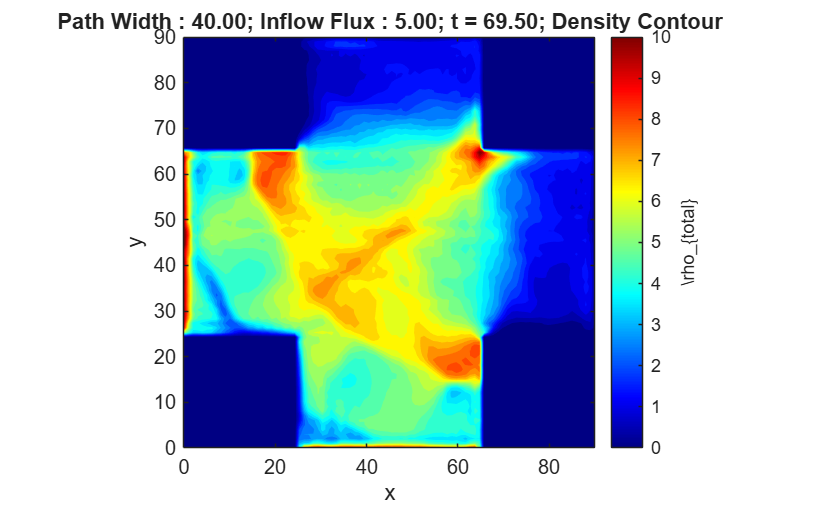

clear all;
clc;

%-------Domain Parameter-----%
% Defining velocity
global INFINITE eta CFL speed_A speed_B discomfort_A discomfort_B cost_A cost_B x_velocity_A y_velocity_A x_velocity_B y_velocity_B;

% Grid Points
global Nx; Nx = 90+6;
global Ny; Ny = 90+6;


%--Important Parameter
INFINITE = 10^12;
eta = 10^-6;
error_eta = 10^-9;
CFL = 0.5;

% To track the error for each iterations
iteration_error = [];

% Dimension of Domain
Lx = 90;
Ly = 90;

% Domain
x = linspace(0,Lx,Nx);
y = linspace(0,Ly,Ny);
[X,Y] = meshgrid(x,y);



% Space Interval
global h;
h = Lx/(Nx-6);

% Total Time
t_total = 400;

% --- Obstacle modeling ----%
global obstacle;
global P1 P2;
% Global variable for pathway width
global width; width = 10;
% Setting up the obstacle
makePathWidth(width);

%-------Initial Condition------% 
global inflow_flux;

% Zero Density initial condition
rho_zeros = zeros(Ny,Nx);
rho = rho_zeros;    % Total Density
rho_a = rho_zeros;  % Density of A
rho_b = rho_zeros;  % Density at B

%------Multiple Crowd Description------%
% Rho_max and V_max
rho_max_a = 10;
rho_max_b = 10;
v_max_a = 2;
v_max_b = 2;
% Discomfort
k_a = 0.002;
k_b = 0.002;

%--Function to compute Velocity using Density
function speed = makeSpeed(rho,v_max,rho_max)
    global Nx Ny;
    speed = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            speed(j,i) = v_max*(1 - rho(j,i)/rho_max);
        end
    end
end

%--Function to compute Discomfort using Density
function discomfort = makeDiscomfort(rho,k)
    global Nx Ny;
    discomfort = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            discomfort(j,i) = k*rho(j,i)*rho(j,i);
        end
    end
end

%--Function to compute Cost function using Speed and Discomfort
function cost = makeCost(speed,discomfort)
    global Nx Ny;
    cost = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            cost(j,i) = 1/speed(j,i) + discomfort(j,i);
        end
    end
end
% Function that will calculate the flux depending on the u,v and Density.
% X_velocity and y_velocity will be found using the potential.
function flux = makeFlux(rho,x_velocity,y_velocity)
    global Nx Ny;

    % Initializing Flux
    flux_x = zeros(Ny,Nx);
    flux_y = zeros(Ny,Nx);
    flux = zeros(2, Ny, Nx);

    for i = 1:1:Nx
        for j = 1:1:Ny
            
            flux_x(j,i) = rho(j,i) * x_velocity(j,i);
            flux_y(j,i) = rho(j,i) * y_velocity(j,i);

            flux(1,j,i) = flux_x(j,i);
            flux(2,j,i) = flux_y(j,i);
        end
    end 
end

% This function will capture the flux at the exits and will return the
% updated matrix.
function matrix = captureOutflow(rho,matrix,type)
    global Nx Ny h;
    global P1 P2;
    global x_velocity_B y_velocity_A;

    total_flux = 0;

    switch type
        case 'A'
            for i = P1 : 1 : P2
                total_flux = total_flux + rho(Ny-3,i) * y_velocity_A(Ny-3,i) * h;
            end
        case 'B'
            for j = P1 : 1 : P2
                total_flux = total_flux + rho(j,Nx-3) * x_velocity_B(j,Nx-3) * h;
            end
    end

    matrix(end+1) = total_flux;
end

% Loop for the Width
for width_set = 20:20:40
    
    % Update the Width
    width = width_set;
    % Update inflow boundary and obstacle according to width
    makePathWidth(width);

    % Make a new folder
    width_folder = sprintf("W_%d", width);
    if ~exist(width_folder, 'dir')
        mkdir(width_folder);
    end

    % Loop for inflow flux
    for inflow_set = 4.0:0.5:5

        % Set the inflow flux
        inflow_flux = inflow_set;

        % Zero Density initial condition
        rho_zeros = zeros(Ny,Nx);
        rho = rho_zeros;    % Total Density
        rho_a = rho_zeros;  % Density of A
        rho_b = rho_zeros;  % Density at B

        %--Pre allocating the memory
        rho_n_A = zeros(Ny,Nx);     rho_n_B = zeros(Ny,Nx);
        rho_1_A = zeros(Ny,Nx);     rho_1_B = zeros(Ny,Nx);
        rho_2_A = zeros(Ny,Nx);     rho_2_B = zeros(Ny,Nx);
        rho_next_A = zeros(Ny,Nx);  rho_next_B = zeros(Ny,Nx);

        % Stopping condition
        stop_low = -1;
        stop_high = 11;

        % This will be used for plotting
        x_plot = linspace(0, Lx, Nx-6);
        y_plot = linspace(0, Ly, Ny-6);

        %-----------MAIN SOLVER------------%
        t = 0; 
        step = 0; % For plotting at regular interval


        % Video Capturing (Density Contour)
        file_name = fullfile(width_folder, sprintf("Combined_Density_L_%.2f_F_%.2f.mp4",width,inflow_flux));
        contour_rho_v = VideoWriter(file_name,"MPEG-4"); 
        contour_rho_v.FrameRate = 30;
        open(contour_rho_v);

        % This will be used to get the flux at the exits. And this will be
        % used to get the possible oscillations for low inflow flux
        outflow_flux_A = [];
        outflow_flux_B = [];
        time_array = [];

        while t < t_total

            % Coupling Term
            rho = rho_a + rho_b;
        
            % Computing cost for the density (rho)
            speed_A = makeSpeed(rho,v_max_a,rho_max_a);
            speed_B = makeSpeed(rho,v_max_b,rho_max_b);
            discomfort_A = makeDiscomfort(rho,k_a);
            discomfort_B = makeDiscomfort(rho,k_b);
            cost_A = makeCost(speed_A,discomfort_A);
            cost_B = makeCost(speed_B,discomfort_B);
        
            %-- Calculate Initial Phi guess using Lower order Fast Sweep
            phi_first_order_A = First_order_Godunov_Fast_Sweep_Algorithm("A",cost_A,h,INFINITE);
            phi_first_order_B = First_order_Godunov_Fast_Sweep_Algorithm("B",cost_B,h,INFINITE);
            %-- Calculate The final phi using higher order scheme and above initial guess 
            phi_A = weno_fastsweep("A",cost_A,h,eta,error_eta,INFINITE,phi_first_order_A,iteration_error);
            phi_B = weno_fastsweep("B",cost_B,h,eta,error_eta,INFINITE,phi_first_order_B,iteration_error);
            % Extrapolation of the phi values
            phi_A = extrapolate_phi(phi_A);
            phi_B = extrapolate_phi(phi_B);
        
            %--Calculate the Components of Velocity
            makeComponent("A",phi_A,speed_A);
            makeComponent("B",phi_B,speed_B);
        
            % Updating the delta_t with proper CFL condition (Stochastic paper)
            u_max = max([abs(x_velocity_A(:)); abs(x_velocity_B(:))]);
            v_max = max([abs(y_velocity_A(:)); abs(y_velocity_B(:))]);
            %dt = CFL / ( ( u_max/h ).^(5/3) + ( v_max/h ).^(5/3) + 1e-12 );
            dt = CFL * h / ( ( u_max ) + ( v_max ) + 1e-12 );
        
            % -------- Making rho_n and RHS of rho_n (Crowd A and B)-----%
            rho_n_A = rho_a; 
            rho_n_B = rho_b;
        
            semi_discritze_form_rho_n_A = makeRHS("A",rho_n_A,t);
            semi_discritze_form_rho_n_B = makeRHS("B",rho_n_B,t);
        
            % Check for the negative rho_n values
            if (any(rho_n_A(:) < stop_low)|| any(rho_n_B(:) < stop_low))
                break
            elseif (any(rho_n_A(:) > stop_high) ||  any(rho_n_B(:) > stop_high))
                break;
            end
            
            % Extrapolation
            rho_n_A = extrapolate_Density("A",rho_n_A);
            rho_n_B = extrapolate_Density("B",rho_n_B);
        
            
            % ---------- Making the RHO_1 and RHS of rho_1 (Crowd A and B)------ %
            for i = 4:1:Nx-3
                for j = 4:1:Ny-3
                    if(~obstacle(j,i))
                        rho_1_A(j,i) = rho_n_A(j,i) + dt * semi_discritze_form_rho_n_A(j-3,i-3);
                        rho_1_B(j,i) = rho_n_B(j,i) + dt * semi_discritze_form_rho_n_B(j-3,i-3);
                    else
                        rho_1_A(j,i) = 0;
                        rho_1_B(j,i) = 0;
                    end
                end
            end
        
        
            % -- Extrapolation (My Intuition)
            rho_1_A = extrapolate_Density("A",rho_1_A);
            rho_1_B = extrapolate_Density("B",rho_1_B);                 
        
            % -- RHS of discretized form using rho_1
            semi_discritze_form_rho_1_A = makeRHS("A",rho_1_A,t);
            semi_discritze_form_rho_1_B = makeRHS("B",rho_1_B,t);
        
            % Check for the negative rho_1 values
            if (any(rho_1_A(:) < stop_low)|| any(rho_1_B(:) < stop_low))
                break
            elseif (any(rho_1_A(:) > stop_high) ||  any(rho_1_B(:) > stop_high))
                break;
            end
        
        
        
            %--------- Making the RHO_2 and RHS of RHO_2 ----------%
            for i = 4:1:Nx-3
                for j = 4:1:Ny-3
                    if(~obstacle(j,i))
                        rho_2_A(j,i) = 3/4 * rho_n_A(j,i) + 1/4 * (rho_1_A(j,i) + dt * semi_discritze_form_rho_1_A(j-3,i-3));
                        rho_2_B(j,i) = 3/4 * rho_n_B(j,i) + 1/4 * (rho_1_B(j,i) + dt * semi_discritze_form_rho_1_B(j-3,i-3));
                    else
                        rho_2_A(j,i) = 0;
                        rho_2_B(j,i) = 0;
                    end
                    
                end
            end
        
        
            % -- Extrapolation (My Intuition)
            rho_2_A = extrapolate_Density("A",rho_2_A);
            rho_2_B = extrapolate_Density("B",rho_2_B);               
        
            % -- RHS of discretized form using rho_2
            semi_discritze_form_rho_2_A = makeRHS("A",rho_2_A,t);
            semi_discritze_form_rho_2_B = makeRHS("B",rho_2_B,t);
        
            % Check for the negative rho_2 values
            if (any(rho_2_A(:) < stop_low)|| any(rho_2_B(:) < stop_low))
                break;
            elseif (any(rho_2_A(:) > stop_high) ||  any(rho_2_B(:) > stop_high))
                break;
            end
        
            %---------- Making the rho_next (Crowd A and B)----------------%
            
            for i = 4:1:Nx-3
                for j = 4:1:Ny-3
                    if(~obstacle(j,i))
                        rho_next_A(j,i) = 1/3 * rho_n_A(j,i) + 2/3 * (rho_2_A(j,i) + dt * semi_discritze_form_rho_2_A(j-3,i-3));
                        rho_next_B(j,i) = 1/3 * rho_n_B(j,i) + 2/3 * (rho_2_B(j,i) + dt * semi_discritze_form_rho_2_B(j-3,i-3));
                    else
                        rho_next_A(j,i) = 0;
                        rho_next_B(j,i) = 0;
                    end
                end
            end  
        
            % -- Extrapolation (My Intuition)
            rho_next_A = extrapolate_Density("A",rho_next_A);
            rho_next_B = extrapolate_Density("B",rho_next_B);
        
            %--Check if any of the density values is equal to zero
            if (any(rho_next_A(:) < stop_low)|| any(rho_next_B(:) < stop_low))
                break;
            elseif (any(rho_next_A(:) > stop_high) ||  any(rho_next_B(:) > stop_high))
                break;
            end
        
            % Substituting back the rho value
            rho_a = rho_next_A;
            rho_b = rho_next_B;
            rho = rho_next_A + rho_next_B;


        
            %--Plotting the rho_next;
            if mod(step, 2) == 0

                figure(7); clf;
                % Density Plot
                density_total = rho(4:Ny-3,4:Nx-3);
                contourf(x_plot, y_plot, density_total, 30, 'LineColor', 'none');
                axis equal tight;
                xlim([0 Lx]);ylim([0 Ly]);
                clim([0 10]);
                colormap(gca, jet);
                cb = colorbar;
                cb.Label.String = '\rho_{total}';
                xlabel('x');ylabel('y');
                title(sprintf('Path Width : %.2f; Inflow Flux : %.2f; t = %.2f; Density Contour', width, inflow_flux, t));
                drawnow;
                % Save this completely separate frame
                frame_2 = getframe(gcf);
                writeVideo(contour_rho_v, frame_2);

            end

            % Capture the flux values
            outflow_flux_A = captureOutflow(rho_a,outflow_flux_A,'A');
            outflow_flux_B = captureOutflow(rho_b,outflow_flux_B,'B');
            time_array(end+1) = t;
        
            % Updating the time
            t = t + dt;
        
            step = step + 1;

            
        end

        % Close the Video
        close(contour_rho_v);

        % Save the CSV file with column Rho and time
        data_A = [outflow_flux_A(:),time_array(:)];
        data_B = [outflow_flux_B(:),time_array(:)];
        file_name_A = fullfile(width_folder, sprintf("Outflow_Flux_W_%.2f_F_%.2f_Crowd_A.csv",width,inflow_flux));
        writematrix(data_A,file_name_A);
        file_name_B = fullfile(width_folder, sprintf("Outflow_Flux_W_%.2f_F_%.2f_Crowd_B.csv",width,inflow_flux));
        writematrix(data_B,file_name_B);

    end
end

% Function to assign P's for width
function makePathWidth(width)
    global P1 P2;
    global obstacle;
    global Nx Ny;

    switch width
        case 10
            P1 = 43; P2 = 54;
        case 20
            P1 = 38; P2 = 59;
        case 30
            P1 = 33; P2 = 64;
        case 40
            P1 = 28; P2 = 69;
    end

    % Update the Obstacle
    obstacle = false(Ny,Nx);
    obstacle(1:P1,1:P1) = true;         % Bottom Left
    obstacle(1:P1,P2:Nx) = true;        % Bottom Right
    obstacle(P2:Ny,4:P1) = true;        % Top Left
    obstacle(P2:Ny,P2:Nx) = true;       % Top Right

end

## Components of Velocity

function makeComponent(type,phi,speed)
    global Nx Ny eta h x_velocity_A y_velocity_A x_velocity_B y_velocity_B;

    [phi_x, phi_y] = gradient(phi, h, h); % partial derivatives of phi in x and y
    mag_phi = sqrt(phi_x.^2 + phi_y.^2);
    mag_phi = max(mag_phi, eta);          % To be safe with denominator

    switch type
        case "A"
            for i = 1:1:Nx
                for j = 1:1:Ny
                    x_velocity_A(j,i) = speed(j,i) * (- phi_x(j,i))/mag_phi(j,i);
                    y_velocity_A(j,i) = speed(j,i) * (- phi_y(j,i))/mag_phi(j,i);
                end
            end 
        case "B"
            for i = 1:1:Nx
                for j = 1:1:Ny
                    x_velocity_B(j,i) = speed(j,i) * (- phi_x(j,i))/mag_phi(j,i);
                    y_velocity_B(j,i) = speed(j,i) * (- phi_y(j,i))/mag_phi(j,i);
                end
            end
    end 
end

## First order Godunov Fast Sweep Algorithm (Older Version)

function phi = First_order_Godunov_Fast_Sweep_Algorithm(type,c,h,INFINITE)
    global Nx Ny obstacle P1 P2;
    phi = INFINITE*ones(Ny, Nx);    % Initial potential field

    % Exit will depend on the type of crowd
    switch type
        case "A"
            phi(Ny-3,(P1+1):(P2-1))= 0; % Top Boundary
        case "B"
            phi((P1+1):(P2-1),Nx-3) = 0; % Right Boundary
    end
    
    % Sweep Iterations
    for sweep = 1:20

        % Sweep 1:
        for i = 4:Nx-2
            for j = 4:Ny-2
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                else
                    phi(j,i) = INFINITE;
                end
            end
        end

        % Extrapolate the Phi
        phi = extrapolatePhi(phi);

        % Sweep 2:
        for i = Nx-1:-1:2
            for j = 2:Ny-1
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                else
                    phi(j,i) = INFINITE;
                end
            end
        end

        % Extrapolate the Phi
        phi = extrapolatePhi(phi);

        % Sweep 3: 
        for i = Nx-1:-1:2
            for j = Ny-1:-1:2
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                else
                    phi(j,i) = INFINITE;
                end
            end
        end

        % Extrapolate the Phi
        phi = extrapolatePhi(phi);

        % Sweep 4:
        for i = 2:Nx-1
            for j = Ny-1:-1:2
                if ~obstacle(j, i)
                    phi = update_phi(phi, c, i, j, h);
                else
                    phi(j,i) = INFINITE;
                end
            end
        end
    
        % Extrapolate the Phi
        phi = extrapolatePhi(phi);
  
    end
end

## Subfunction: Update one grid point using Godunov scheme

function phi = update_phi(phi, c, i, j, dx)
    a = min(phi(j, i-1), phi(j, i+1)); % x-direction neighbors
    b = min(phi(j-1, i), phi(j+1, i)); % y-direction neighbors
    c_i = c(j, i); % Local inverse speed
    if abs(a - b) >= c_i * dx
        phi(j, i) = min(a, b) + c_i * dx;
        else
            inside = 2 * (c_i * dx)^2 - (a - b)^2;
        if inside >= 0
            phi(j, i) = (a + b + sqrt(inside)) / 2;
        end
    end
end


## Extrapolate the Phi Values

% Function will extrapolate the phi values at the boundary
function phi = extrapolatePhi(phi)
    global Nx Ny;
    % Bottom Edge   (3 Ghost Points)
    phi(3,:) = phi(4,:); 
    phi(2,:) = phi(3,:); 
    phi(1,:) = phi(2,:);
    
    % Top Edge      (3 Ghost Points)
    phi(Ny-3,:) = phi(Ny-2,:); 
    phi(Ny-1,:) = phi(Ny-2,:); 
    phi(Ny,:) = phi(Ny-1,:);
    
    % Right Edge    (3 Ghost Points)
    phi(:,Nx-3) = phi(:,Nx-2); 
    phi(:,Nx-1) = phi(:,Nx-2); 
    phi(:,Nx) = phi(:,Nx-1);
    
    % Left Edge     (3 Ghost Points)
    phi(:,3) = phi(:,4); 
    phi(:,2) = phi(:,3); 
    phi(:,1) = phi(:,2);
end

## WENO FAST SWEEP

function phi = weno_fastsweep(type,c,h,eta,error_eta,INFINITE,initial_guess,iteration_error)

    global Nx Ny obstacle P1 P2;

    % Phi is initialized with infinity
    phi = initial_guess;
    phi_old = INFINITE * ones(size(phi));

    % Iterations
    iterations = 0;
    loop_safety = 0;

    % Iterations
    while (sum(abs(phi(:)-phi_old(:))) > error_eta && loop_safety<1000)

        %fprintf("Iteration = %d ",iterations);
        err = sum(abs(phi(:)-phi_old(:)));
        %fprintf("Error = %0.10f\n",err);

        phi_old = phi;
        iterations = iterations + 1;
        iteration_error(iterations) = err;
        loop_safety = loop_safety + 1;

        for sweep = 1:4
            switch sweep
                case 1 
                    ix = 4:1:Nx-3; jy = 4:1:Ny-3;
                case 2 
                    ix = 4:1:Nx-3; jy = Ny-3:-1:4;
                case 3 
                    ix = Nx-3:-1:4; jy = 4:1:Ny-3;
                case 4 
                    ix = Nx-3:-1:4; jy = Ny-3:-1:4;
            end 

            for i = ix
                for j = jy
                    %if the point is outside the obstacle
                    if(~obstacle(j,i))
                        %------------Calculating the phix_min---------_%

                        r_back = (eta + (phi(j,i) - 2*phi(j,i-1) + phi(j,i-2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j,i+1) + phi(j,i+2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
    
                        % Calculate the w
                        w_front = 1/(1+2*(r_front^2));
                        w_back = 1/(1+2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phix_minus = (1-w_back)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_back*((3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2))/(2*h));
                        phix_plus = (1-w_front)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_front*((-3*phi(j,i)+4*phi(j,i+1)-phi(j,i+2))/(2*h));
                        
                        
                        phix_min = min((phi(j,i) - h*phix_minus),(phi(j,i) + h*phix_plus));
                        
                        %-----------calculating the phiy_min---------%

                        r_back = (eta + (phi(j,i) - 2*phi(j-1,i) + phi(j-2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j+1,i) + phi(j+2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
    
                        % Calculate the w
                        w_front = 1 / (1 + 2*(r_front^2));
                        w_back = 1 / (1 + 2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phiy_minus = (1-w_back) * ((phi(j+1,i)-phi(j-1,i))/(2*h)) + w_back * ((3*phi(j,i) - 4*phi(j-1,i) + phi(j-2,i))/(2*h));
                        phiy_plus = (1-w_front) * ((phi(j+1,i) - phi(j-1,i))/(2*h)) + w_front * ((-3*phi(j,i) + 4*phi(j+1,i) - phi(j+2,i))/(2*h));
                        
                        
                        phiy_min = min((phi(j,i) - h*phiy_minus), (phi(j,i) + h*phiy_plus));

                        if abs(phix_min - phiy_min) >= c(j,i)*h
                            phi(j,i) = min(phiy_min,phix_min) + c(j,i)*h;
                        else
                            phi(j,i) = ((phix_min + phiy_min) + (2*(c(j,i)*h)^2 - (phix_min - phiy_min)^2)^0.5)/2;
                        end

                        % Enforce the value of phi to be zero at exits depending on the crowd
                        switch type
                            case "B"
                                % Right Boundary
                                if(i == Nx-3 && (j >= (P1+1) && j <= (P2-1)))
                                    phi(j,i) = 0;
                                end
                            case "A"
                                % Top Boundary
                                if(j == Ny-3 && (i >= (P1+1) && i <= (P2-1)))
                                    phi(j,i) = 0;
                                end
                        end

                    % If the point is inside the obstacle
                    else 
                        phi(j,i) = INFINITE;
                    end 
                end
            end
        end   
    end
end


## Extrapolate Phi

function phi = extrapolate_phi(phi)
    global Ny Nx; 
    % Bottom Edge   (3 Ghost Points)
    phi(3,:) = phi(4,:); 
    phi(2,:) = phi(3,:); 
    phi(1,:) = phi(2,:);  
    % Top Edge      (3 Ghost Points)
    phi(Ny-2,:) = phi(Ny-3,:);
    phi(Ny-1,:) = phi(Ny-2,:); 
    phi(Ny,:) = phi(Ny-1,:);             
    % Right Edge    (3 Ghost Points)
    phi(:,Nx-2) = phi(:,Nx-3);
    phi(:,Nx-1) = phi(:,Nx-2); 
    phi(:,Nx) = phi(:,Nx-1);             
    % Left Edge     (3 Ghost Points)
    phi(:,3) = phi(:,4); 
    phi(:,2) = phi(:,3); 
    phi(:,1) = phi(:,2);
end

## RHS of Semi Discretize Form

function semi_discrite_form =  makeRHS(type,rho,t)
    global Nx Ny x_velocity_A y_velocity_A x_velocity_B y_velocity_B h obstacle P1 P2 inflow_flux;
    semi_discrite_form = zeros(Ny-6,Nx-6);

    % Flux for the given rho distribution (Will depend on the type of crowd)
    switch type
        case "A"
            x_velocity = x_velocity_A;
            y_velocity = y_velocity_A;
        case "B"
            x_velocity = x_velocity_B;
            y_velocity = y_velocity_B;
    end
    flux = makeFlux(rho, x_velocity, y_velocity);
    flux_x = squeeze(flux(1,:,:));
    flux_y = squeeze(flux(2,:,:));

    % Calculating the maximum speed (multiplying by 1.5 as suggested)
    alpha_x = max(abs(x_velocity(:))) * 1.5;
    alpha_y = max(abs(y_velocity(:))) * 1.5;


    % -- Calculating the value of f+ and f- at {i+2,i+1,i,i-1,i-2,i-3} -- %
    fx_negative_whole = zeros(Ny,Nx);
    fx_positive_whole = zeros(Ny,Nx);
    fy_negative_whole = zeros(Ny,Nx);
    fy_positive_whole = zeros(Ny,Nx);

    for j = 1:1:Ny
        for i=1:1:Nx
            fx_positive_whole(j,i) = 1/2 * (flux_x(j,i) + alpha_x*rho(j,i));
            fx_negative_whole(j,i) = 1/2 * (flux_x(j,i) - alpha_x*rho(j,i));
            fy_positive_whole(j,i) = 1/2 * (flux_y(j,i) + alpha_y*rho(j,i));
            fy_negative_whole(j,i) = 1/2 * (flux_y(j,i) - alpha_y*rho(j,i));
        end
    end
    
    % -- Computing the RHS of Semi Discrete form.
    for i = 4:1:Nx-3
        for j = 4:1:Ny-3
            % compute only at the points where obstacle doesn't exist
            if(~obstacle(j,i))
                %--X--%
    
                % fx{+}_[i+1/2,j] - Given in the paper
                fx_plus_x_half_forward = stencil( ...
                    fx_positive_whole(j,i-2), ...
                    fx_positive_whole(j,i-1), ...
                    fx_positive_whole(j,i), ...
                    fx_positive_whole(j,i+1), ...
                    fx_positive_whole(j,i+2));
                
                % fx{+}_[i-1/2,j] - By substituting i -> (i-1) in fx{+}_[i+1/2,j]
                fx_plus_x_half_backward = stencil( ...
                    fx_positive_whole(j,i-3), ...
                    fx_positive_whole(j,i-2), ...
                    fx_positive_whole(j,i-1), ...
                    fx_positive_whole(j,i), ...
                    fx_positive_whole(j,i+1));
    
                % fx{-}_[i+1/2,j] ( mirror of fx{+}_[i+1/2,j] )
                fx_minus_x_half_forward = stencil( ...
                    fx_negative_whole(j,i+3), ...
                    fx_negative_whole(j,i+2), ...
                    fx_negative_whole(j,i+1), ...
                    fx_negative_whole(j,i), ...
                    fx_negative_whole(j,i-1));
                
                % fx{-}_[i-1/2,j] ( mirror of fx{+}_[i-1/2,j] )
                fx_minus_x_half_backward = stencil( ...
                    fx_negative_whole(j,i+2), ...
                    fx_negative_whole(j,i+1), ...
                    fx_negative_whole(j,i), ...
                    fx_negative_whole(j,i-1), ...
                    fx_negative_whole(j,i-2));
    
                %--Y--%
    
                % fy{+}_[i,j+1/2]
                fy_plus_y_half_forward = stencil( ...
                    fy_positive_whole(j-2,i), ...
                    fy_positive_whole(j-1,i), ...
                    fy_positive_whole(j,i), ...
                    fy_positive_whole(j+1,i), ...
                    fy_positive_whole(j+2,i));
                
                % fy{+}_[i,j-1/2]
                fy_plus_y_half_backward = stencil( ...
                    fy_positive_whole(j-3,i), ...
                    fy_positive_whole(j-2,i), ...
                    fy_positive_whole(j-1,i), ...
                    fy_positive_whole(j,i), ...
                    fy_positive_whole(j+1,i));
    
                % fy{-}_[i,j+1/2]
                fy_minus_y_half_forward = stencil( ...
                    fy_negative_whole(j+3,i), ...
                    fy_negative_whole(j+2,i), ...
                    fy_negative_whole(j+1,i), ...
                    fy_negative_whole(j,i), ...
                    fy_negative_whole(j-1,i));
                
                % fy{-}_[i,j-1/2]
                fy_minus_y_half_backward = stencil( ...
                    fy_negative_whole(j+2,i), ...
                    fy_negative_whole(j+1,i), ...
                    fy_negative_whole(j,i), ...
                    fy_negative_whole(j-1,i), ...
                    fy_negative_whole(j-2,i));
                
                fx_positive_half = fx_plus_x_half_forward + fx_minus_x_half_forward;
                fx_negative_half = fx_plus_x_half_backward + fx_minus_x_half_backward;
                fy_positive_half = fy_plus_y_half_forward + fy_minus_y_half_forward;
                fy_negative_half = fy_plus_y_half_backward + fy_minus_y_half_backward;
    
    
                %--Boundary Condition -- %
    
                switch type 
                    case "A"
                        % Bottom Boundary (Inflow)
                        if(j == 4 && (i >= (P1+2) && i <= (P2-2)))
                            % Y flux is said to be zero at the inflow
                            fx_negative_half = 0;
                            % Unsteady Boundary Condition (for the x flux)
                            fy_negative_half = inflow_flux;
                        
                        % Right Boundary (Wall)
                        elseif(i == Nx-3 && (j >= (P1+1) && j <= (P2-1)))
                            fx_positive_half = 0;
                        % Left Boundary (Wall)
                        elseif(i == 4 && (j >= (P1+1) && j <= (P2-1)))
                            fx_negative_half = 0;
                        % Top Boundary (Outflow)
                        elseif(j == Ny-3 && (i >= (P1+1) && i <= (P2-1)))
                            fy_positive_half = flux_y(j,i);
                        end
                    case "B"
                        % Left Boundary (Inflow)
                        if(i == 4 && (j >= (P1+2) && j <= (P2-2)))
                            % Y flux is said to be zero at the inflow
                            fy_negative_half = 0;
                            % Unsteady Boundary Condition (for the x flux)
                            fx_negative_half = inflow_flux;

                        % Top Boundary (Wall)
                        elseif(j == Ny-3 && (i >= (P1+1) && i <= (P2-1)))
                            fy_positive_half = 0;

                        % Right Boundary (Outflow)
                        elseif(i == Nx-3 && (j >= (P1+1) && j <= (P2-1)))
                            fx_positive_half = flux_x(j,i);

                        % Bottom Boundary (Wall)
                        elseif(j == 4 && (i >= (P1+1) && i <= (P2-1)))
                            fy_negative_half = 0;
                        end
                end

                % BOUNDARY OF OBSTACLE

                % Obstacle 1 (Bottom Left Obstacle)
                if(i >= 4 && i <= P1 && j == (P1+1))
                    fy_negative_half = 0; % Top Boundary
                elseif(j >= 4 && j <= P1 && i == (P1+1))
                    fx_negative_half = 0; % Right Boundary
                end

                % Obstacle 2 (Top Left Obstacle)
                if(i >= 4 && i <= P1 && j == (P2-1))
                    fy_positive_half = 0;
                elseif(j >= P2 && j <= Ny-3 && i == (P1+1))
                    fx_negative_half = 0;
                end

                % Obstacle 3 (Bottom Right Obstacle)
                if(i >= P2 && i <= Nx-3 && j == (P1+1))
                    fy_negative_half = 0;
                elseif(i == (P2-1) && j >= 4 && j <= P1)
                    fx_positive_half = 0;
                end

                % Obstacle 4 (Top Right Obstacle)
                if(i >= P2 && i<= Nx-3 && j == (P2-1))
                    fy_positive_half = 0;
                elseif(i == (P2-1) && j >= P2 && j <= Ny-3)
                    fx_positive_half = 0;
                end

                % Computing RHS of Semi Discretized form
                semi_discrite_form(j-3,i-3) = - 1/h * (fx_positive_half - fx_negative_half) - 1/h * (fy_positive_half - fy_negative_half);
            
            else
                % Else when there is an obstacle
            end    
        end
    end
end

## WENO Advection Stencil

% To compute f half. Order of input matters
function f = stencil(f1,f2,f3,f4,f5)

    eta = 10^-6;

    % Compute S values
    s_1 = ((1/3) * f1) + ((-7/6) * f2) + ((11/6) * f3);
    s_2 = ((-1/6) * f2) + ((5/6) * f3) + ((1/3) * f4);
    s_3 = ((1/3) * f3) + ((5/6) * f4) + ((-1/6) * f5);

    % Compute Beta
    beta_1 = 13/12 * (f1 - 2*f2 + f3)^2 + 1/4 * (f1 - 4*f2 + 3*f3)^2;
    beta_2 = 13/12 * (f2 - 2*f3 + f4)^2 + 1/4 * (f2 - f4)^2;
    beta_3 = 13/12 * (f3 - 2*f4 + f5)^2 + 1/4 * (3*f3 - 4*f4 + f5)^2;

    % Defining Gamma
    gamma_1 = 1/10;
    gamma_2 = 3/5;
    gamma_3 = 3/10;

    % Computing weights bar
    w_1_dash = ( gamma_1 ) ./ ((eta + beta_1)^2);
    w_2_dash = ( gamma_2 ) ./ ((eta + beta_2)^2);
    w_3_dash = ( gamma_3 ) ./ ((eta + beta_3)^2);

    % Computing Weights
    w_1 = ( w_1_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_2 = ( w_2_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_3 = ( w_3_dash ) / (w_1_dash + w_2_dash + w_3_dash);

    % Computing Flux
    f = w_1 * s_1 + w_2 * s_2 + w_3 * s_3;
end


## Density Extrapolation

function rho = extrapolate_Density(type,rho)
    global Ny Nx; 
    % Left Edge     (3 Ghost Points)
    rho(:,3) = rho(:,4); 
    rho(:,2) = rho(:,3); 
    rho(:,1) = rho(:,2);
    % Bottom Edge   (3 Ghost Points)
    rho(3,:) = rho(4,:); 
    rho(2,:) = rho(3,:); 
    rho(1,:) = rho(2,:);
    % Top Edge      (3 Ghost Points)
    rho(Ny-2,:) = rho(Ny-3,:); 
    rho(Ny-1,:) = rho(Ny-2,:); 
    rho(Ny,:) = rho(Ny-1,:);
    % Right Edge    (3 Ghost Points)
    rho(:,Nx-2) = rho(:,Nx-3);
    rho(:,Nx-1) = rho(:,Nx-2); 
    rho(:,Nx) = rho(:,Nx-1);
end